syms clear
clear

syms z
syms L
L=1;
N_1 = 1 - 3 * z^2 + 2 * z^3

$$N\_1 = 2\,z^{3}-3\,z^{2}+1$$

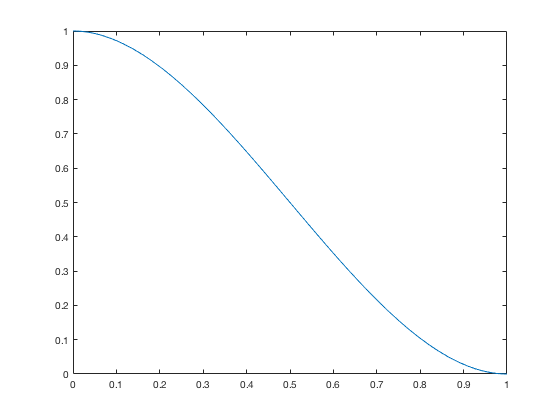

figure
fplot(N_1, [0, 1])


N_3 = 3 * z^2 - 2 * z^3

$$N\_3 = 3\,z^{2}-2\,z^{3}$$

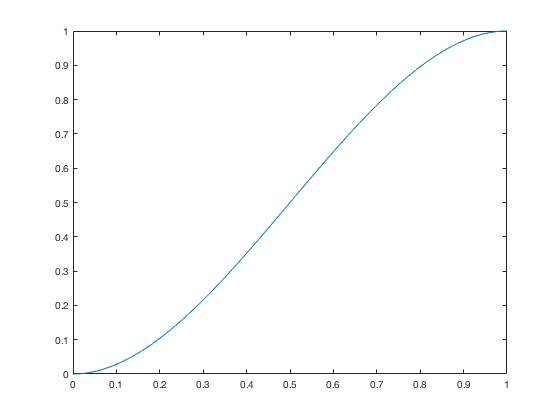

figure
fplot(N_3, [0, 1])

N_2 = L * z * (z - 1)^2

$$N\_2 = z\,{\left(z-1\right)}^{2}$$

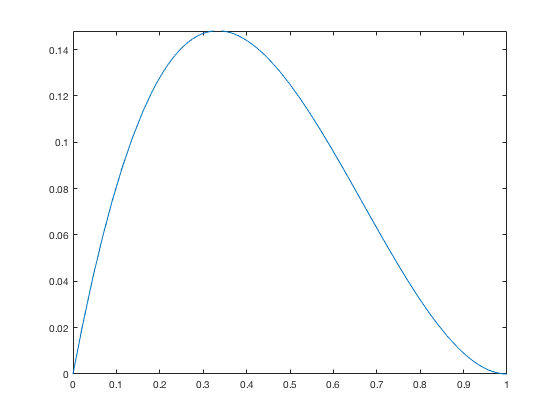

figure
fplot(N_2, [0, 1])

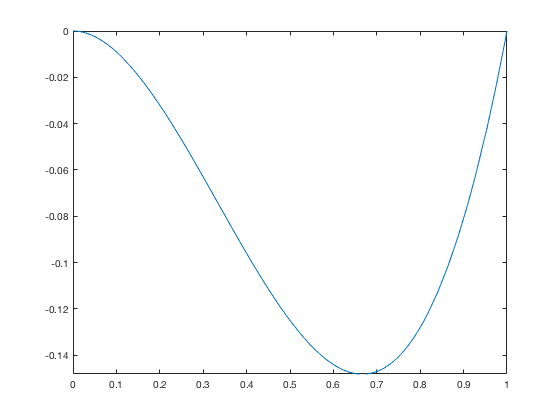

N_4=-L*(z^2-z^3);
figure
fplot(N_4, [0, 1])

syms X
N_1 = subs(N_1, z, X/L)

$$N\_1 = 2\,X^{3}-3\,X^{2}+1$$

N_2 = subs(N_2, z, X/L)

$$N\_2 = X\,{\left(X-1\right)}^{2}$$

N_3 = subs(N_3, z, X/L)

$$N\_3 = 3\,X^{2}-2\,X^{3}$$

N_4 = subs(N_4, z, X/L)

$$N\_4 = X^{3}-X^{2}$$


N = [N_1; N_2; N_3; N_4]

$$N = \left(\begin{array}{c} 2\,X^{3}-3\,X^{2}+1\\ X\,{\left(X-1\right)}^{2}\\ 3\,X^{2}-2\,X^{3}\\ X^{3}-X^{2} \end{array}\right)$$


B = symhold('transpose(diff(diff(N, X), X))')

$$B = {\left(\frac{\partial }{\partial X}\frac{\partial }{\partial X}N\right)}^{t}$$


B = transpose(diff(diff(N, X), X))

$$B = \left(\begin{array}{cccc} 12\,X-6 & 6\,X-4 & 6-12\,X & 6\,X-2 \end{array}\right)$$


syms K
K = symhold('EI*int(transpose(B)*B, X, 0, L)')

$$K = \mathrm{EI}\,\int B^{t}\,B\mathrm{d}X$$


syms EI
K = EI * int(transpose(B) * B, X, sym(0), L)

$$K = \left(\begin{array}{cccc} 12\,\mathrm{EI} & 6\,\mathrm{EI} & -12\,\mathrm{EI} & 6\,\mathrm{EI}\\ 6\,\mathrm{EI} & 4\,\mathrm{EI} & -6\,\mathrm{EI} & 2\,\mathrm{EI}\\ -12\,\mathrm{EI} & -6\,\mathrm{EI} & 12\,\mathrm{EI} & -6\,\mathrm{EI}\\ 6\,\mathrm{EI} & 2\,\mathrm{EI} & -6\,\mathrm{EI} & 4\,\mathrm{EI} \end{array}\right)$$

## Local Functions

## Helpers

function h = symhold(exprstring)
h = evalin(symengine, ['hold(' exprstring ' )']);
end